# Chapter 5 ATAP Exercises

## Barycentric Interpolation Formula

#### Mason Mault June 2025

Worked exercises

Exercise 5.2: Instability of Vandermonde interpolation

Exercise 5.11: Barycentric Interpolation in Legendre Points

The second barycentric form given in Theorem 5.2 is derived in my BarycentricInterpolation note, and is implemented in my discreteChebyshecTransform_barycentricInterpolation_FFT.mlx .

**Exercise 5.2: Instability of Vandermonde interpolation**

The best known numerical algorithm for polynomial interpolation is unstable. This is the method implemented by MATLABS polyfit command, forming a Vandermonde matrix of sampled powers of x, then solving the corresponding linear system. 

Here, the instability is explored by comparison to Chebyshev interpolation, specifically, the evaluation of the interpolation at 0, for the function

$f\left(x\right)=\cos \left(\textrm{kx}\right)$ for k = 10, 20, ..., 100

The Vandermonde matrix $V$ is constructed for each of these 10 problems, and its condition number is computed

% build  a "fine grid"
fine = 1e4;
xx = linspace(-1, 1, fine);

% initialization
fkEval = zeros(10, 1);
pkEval = zeros(10, 1);
condNum = zeros(10, 1);

% start at k = 10, take steps of 10, until k = 100
for k = 10:10:100   
    % account for steps of 10 in index
    fk = @(x) cos(k*x);
    fkEval(k/10) = fk(0);
    pkEval(k/10) = polyval(polyfit(xx, fk(xx), k), 0);

    % build vandermonde matrix up to degree k, compute condition number
    V = vander(xx);
    V = V(:, end - k : end);
    condNum(k/10) = cond(V);
end

MATLAB throws up all over the screen!

The following table summarizes the interpolants evaluation at $x=0$ as $k$ increases, and shows the Vandermondes condition number. Chebfun is consistently accurate as it uses numerically stable Barycentric interpolation, while MATLABS polyfit command is incorrect, actually increasingly incorrect as $k$ increases due to the ill conditioned Vandermonde matrix. 

k = (1:length(pkEval))'; 

T = table(k, pkEval(:), fkEval(:), condNum(:), ...
    'VariableNames', {'k', 'Polyfit_Eval_at_0', 'Chebfun_Eval_at_0', 'Vandermonde_CondNum'});

disp(T)

    k     Polyfit_Eval_at_0    Chebfun_Eval_at_0    Vandermonde_CondNum
    __    _________________    _________________    ___________________

     1          0.8824                 1                      3071     
     2         0.85169                 1                1.7682e+07     
     3         0.83447                 1                1.0838e+11     
     4         0.79813                 1                6.8226e+14     
     5        -0.33647                 1                1.5294e+17     
     6          0.1722                 1                2.1479e+17     
     7        0.019471                 1                3.0255e+17     
     8        0.078198                 1                2.5196e+18     
     9         0.10132                 1                6.0523e+18     
    10         0.13528                 1                3.6814e+18     

condNum = 1.0e+18 *

    0.0000
    0.0000
    0.0000
    0.0007
    0.1529
    0.2148
    0.3026
    2.5196
    6.0523
    3.6814


**Exercise 5.11: Barycentric Interpolation in Legendre Points**

Compare the accuracy of interpolants in Chebyshev and Legendre points for the function

$f\left(x\right)=\exp \left(x\right)\;\sin \left(300x\right)$ at $x=0\ldotp 99$.

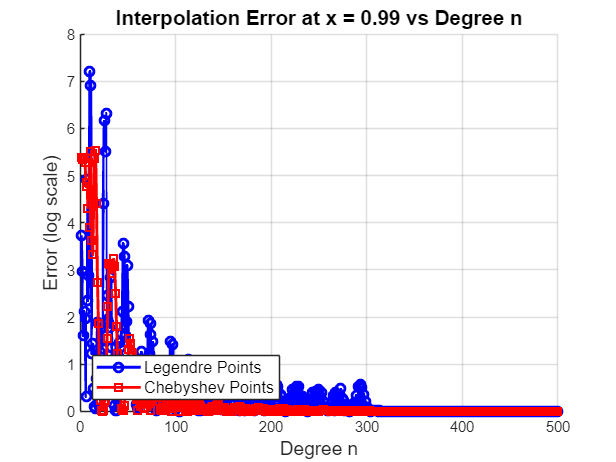

x = chebfun('x');
f = exp(x)*sin(300*x);

% number of iterations
niter = 500;

% initialization
legEval = zeros(niter, 1);
chebEval = zeros(niter, 1);
legErr = zeros(niter, 1);
chebErr = zeros(niter, 1);

% evaluate f(x) at x = 0.99 using both point sets
for n = 1:niter
    [s, w, lambda] = legpts(n + 1);
    legEval(n) = bary(0.99, f(s), s, lambda);
    legErr(n) = abs(legEval(n) - f(0.99));

    [s2, w2, lambda2] = chebpts(n + 1);
    chebEval(n) = bary(0.99, f(s2), s2, lambda2);
    chebErr(n) = abs(chebEval(n) - f(0.99));
end

% plot error vs n for both points
figure
hold on
semilogy(legErr, '-ob', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Legendre Points')
semilogy(chebErr, '-sr', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Chebyshev Points')

xlabel('Degree n', 'FontSize', 13)
ylabel('Error (log scale)', 'FontSize', 13)
title('Interpolation Error at x = 0.99 vs Degree n', 'FontSize', 14)

legend('Location', 'southwest', 'FontSize', 11)
grid on
xlim([0, 500])

Evaluation at $x=0\ldotp 99$ shows how well the interpolants hug the true function near endpoints, which are known to be problematic (the Runge phenomenon).

The Chebyshev points give less error for almost all values of $n$.

Both point sets oscillate wrt error as a function of $n$.